# TNA005: Tillämpad matematik i teknik och naturvetenskap

## Examination: UPG9 Introduktion till MATLAB

## Datum: 2021-08-20

## Namn: förnamn efternamn 

## Personnummer: yyyymmdd-xxxx

## LiU-ID: abcde???

## Klass: ???

## Uppgift 1

Förklara din kod antingen här, eller som kommentarer i kod-blocken. 

% Skriv din kod här:
clear 
% a
% rand1 tar ints 1 - 4
n = 4 + randi(4)

n =      6


A = zeros(n)

A =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


for i = 1:n
    for j = 1:n
        A(i, j) = 1/(i+j-1);
    end
end
A

A =    1.000000000000000   0.500000000000000   0.333333333333333   0.250000000000000   0.200000000000000   0.166666666666667
   0.500000000000000   0.333333333333333   0.250000000000000   0.200000000000000   0.166666666666667   0.142857142857143
   0.333333333333333   0.250000000000000   0.200000000000000   0.166666666666667   0.142857142857143   0.125000000000000
   0.250000000000000   0.200000000000000   0.166666666666667   0.142857142857143   0.125000000000000   0.111111111111111
   0.200000000000000   0.166666666666667   0.142857142857143   0.125000000000000   0.111111111111111   0.100000000000000
   0.166666666666667   0.142857142857143   0.125000000000000   0.111111111111111   0.100000000000000   0.090909090909091


% b
r = rand(n, 1)

r =    0.049654430325742
   0.902716109915281
   0.944787189721646
   0.490864092468080
   0.489252638400019
   0.337719409821377


b = A*r

b =    1.092794667624518
   0.789889937433145
   0.625106784561228
   0.519225761634965
   0.444844526390009
   0.389501064464335


b

b =    1.092794667624518
   0.789889937433145
   0.625106784561228
   0.519225761634965
   0.444844526390009
   0.389501064464335


x = A\b

x =    0.049654430326029
   0.902716109907530
   0.944787189772145
   0.490864092340184
   0.489252638538424
   0.337719409767666



diff = abs(x - r)

diff = 	1.0e+-9 *

   0.000287159185319
   0.007750911024118
   0.050499271431192
   0.127895916079979
   0.138405065186475
   0.053711646241794


[maxAvikelse, indAvvikelse] = max(diff)

maxAvikelse =      1.384050651864754e-10


indAvvikelse =      5


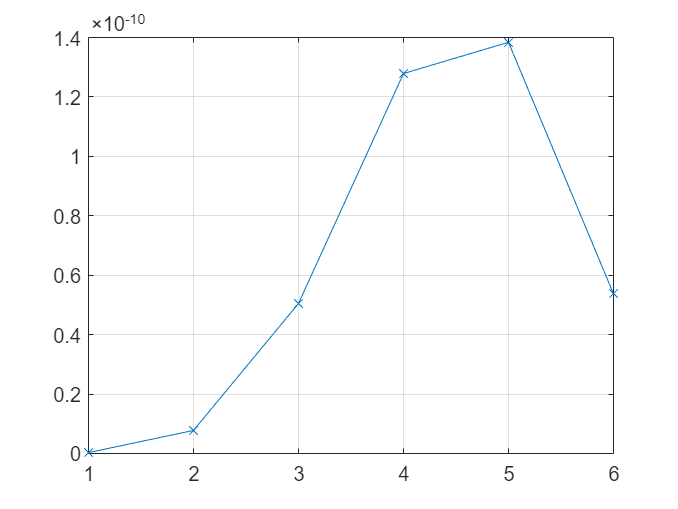

plot(diff, '-x'); 
grid on

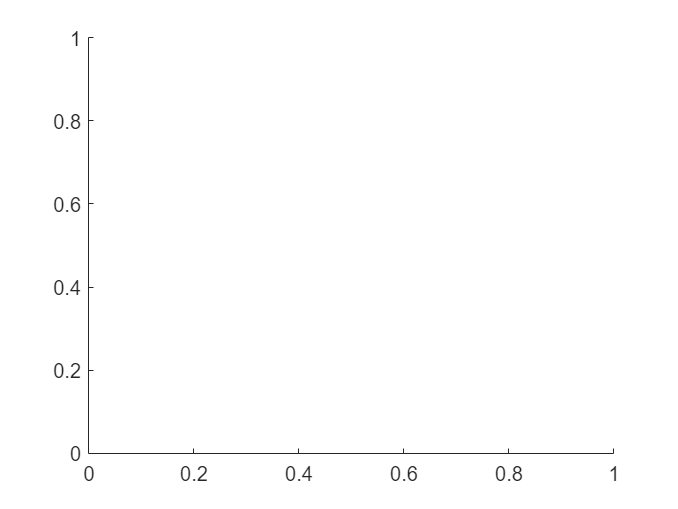

clf
cla

## Uppgift 2

Förklara din kod antingen här, eller som kommentarer i kod-blocken. 

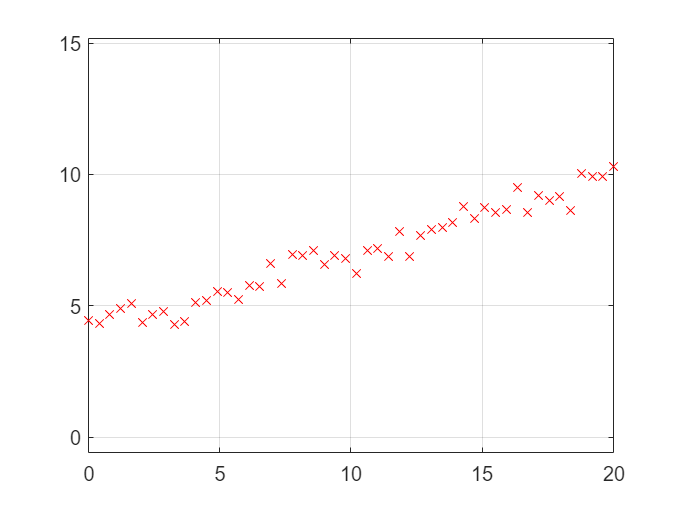

% Skriv din kod här:
clear 
%hold off
load('data20210820.mat')
plot(x, y, 'rx')
axis equal
grid on

% Förklara koden
% Dra slutsater och 
% svara på ställda frågor, 

xm = mean(x)

xm =     10


ym = mean(y)

ym =    6.978131009792241


Sxx = sum((x-xm).*(x-xm))

Sxx =      1.734693877551021e+03


Sxy = sum((x - xm) .* (y - ym))

Sxy =      5.090698116838000e+02


beta = Sxy/Sxx

beta =    0.293463773794191


alpha = ym - beta*xm

alpha =    4.043493271850336


linje = alpha + beta*x

linje =    4.043493271850336
   4.163274404011230
   4.283055536172124
   4.402836668333018
   4.522617800493912
   4.642398932654807
   4.762180064815700
   4.881961196976595
   5.001742329137489
   5.121523461298382


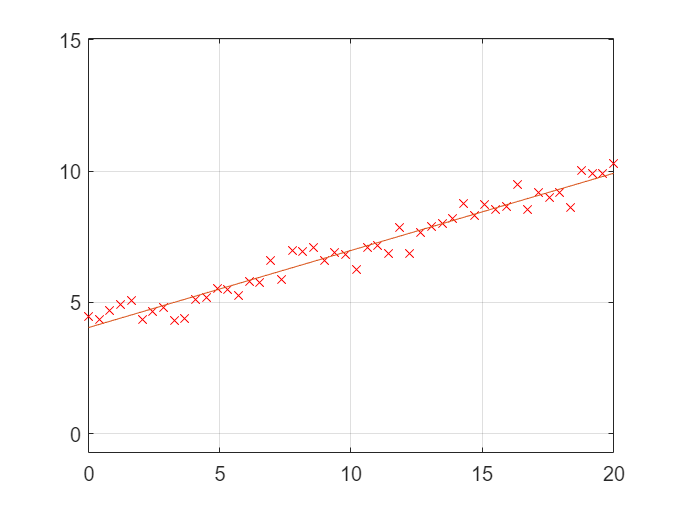

hold on
plot(x, linje, '-')

clf
cla

% c
ei = y - linje

ei =    0.408033366895252
   0.177539483919713
   0.403201780287630
   0.503956385115190
   0.562262491902233
  -0.291784103757393
  -0.106638518671696
  -0.081784679507847
  -0.698141409817623
  -0.732382098221367


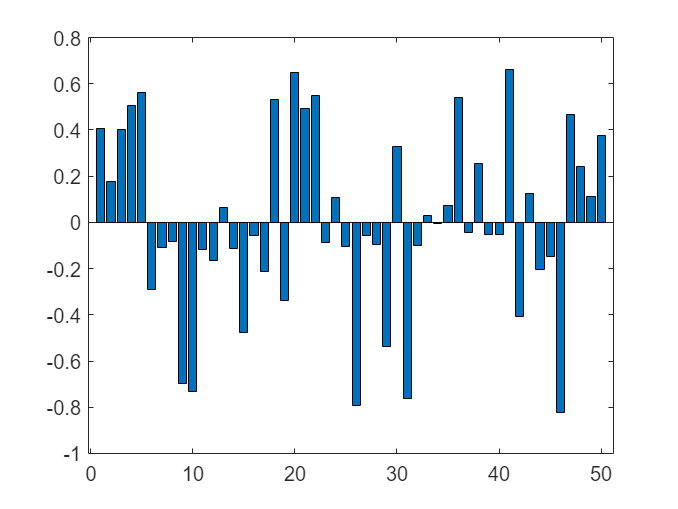

bar(ei)

## Uppgift 3

Förklara din kod antingen här, eller som kommentarer i kod-blocken.  

clear 
n = 9 + randi(11)

n =     19


fun = @(x) sin(x)

fun = function_handle with value:
    @(x)sin(x)


a = 0

a =      0


b = pi

b =    3.141592653589793


I = duggaFunc(fun, a, b, n)

I =    1.995441318320194



fel = abs(I - 2)

fel =    0.004558681679806


clear
fun = @(x) sin(x);
a = 0;
b = pi;
n = 10;
I = duggaFunc(fun, a, b, n);
while abs(2 - I) > 1e-7
    n = n + 1;
    I = duggaFunc(fun, a, b, n);
end
n

n =         4056


format long
I

I =    1.999999900010917


abs(2 - I)

ans =      9.998908279129637e-08
